# JoyStick Demo - Gator Summer 2022

### REV A

Joystick Demo to drive the Gator via a usb connected joystick to the main system

%%% Path Declaration
addpath(...
    "ACT\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\",...
    "TESTING\","RTK_GPS\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


Found Start 1


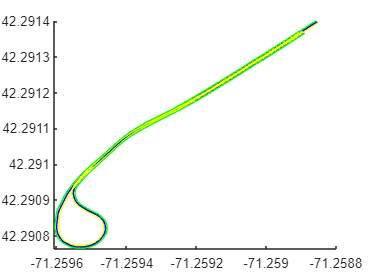

%%% SETUP GPS MAP
waypoints=ConfigureWaypoint("RTK_GPS\GPS_Right_Forest_True.ubx","RTK_GPS\GPS_Left_Forest_True.ubx");

%setupGPSDemo(Mega,GPS1,GPS2);
objects1 = setupGPSDemo('COM7','COM1','COM3');

Warning! RoboClaw must be OFF before running this code
Lights ON = CONNECTED
Please Power up RoboClaw Now
MEGA CONNNECTED
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 1608. 
^C1. Connect to GPS sensor with 38400 Buad (Check Device Manager for COM #)
2. ClickNTRIP Client Settings
3. Credientals 1:IP address: 66.128.64.251Port: 31000Username: cbabePassword: deere1#
4. Click Mount Point details and select RTCM3_MAMI (MAMI is the closest RTK Station)
5. Green lights should blink on both the NTRIP and Serial connections
5. RTK data should be sending to the GPS (On the GPS-RTK-SMA ZED-F9P the Green RTK light should blink and eventually turn off after the GPS gets an RTK fix)
After configuring STRSVR press any button to continue
GPS1 AND GPS2 CONNNECTED


%%% MAIN

% Variable Setup
wayStep=1

wayStep =      1


controlFlag = 1;  

% Init voltage control
senseobjects=sense(objects1)
[motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);

motorControls.throttle=0;
motorControls.steer=0;
oldmotorControls  = struct( ...
    "throttle", [],...
    "steer",[]);
actGPS(objects1.Mega, motorControls,oldmotorControls)
oldmotorControls=motorControls

disp("Turn on Linear Actuators") 
pause
% Main Loop
while (controlFlag > 0)           % loop for number of elements in t
    t1 = tic;
    % Sense
    t2=tic;
    senseobjects = sense(objects1);
    sense1=toc(t2)
    % Think
    [motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);
    motorControls;

    % Act
    %t4=tic;
    actGPS(objects1.Mega, motorControls,oldmotorControls);
    %act=toc(t4)

    % Post-loop cleanup
    controlFlag = controlFlag+1;         % increment loops

    % End-of-path checker
    if wayStep>size(waypoints,2)
        disp("END")
        motorControls.throttle=-1;
        actGPS(objects1.Mega, motorControls,oldmotorControls)
        break 
    end
    % Update MotorControls
    oldmotorControls=motorControls; 
    
    % Current Waypoint
    wayStep;
    wholeloop = toc(t1)
end 

%%% SHUTDOWN
clear